# Test network with new image

Load the networks and investigate the size of each network.

load ../data/bestExperimentNetworks.mat
whos bestTrainedFromScratch bestTransferLearning 

  Name                        Size               Bytes  Class            Attributes

  bestTrainedFromScratch      1x1               123770  SeriesNetwork              
  bestTransferLearning        1x1             24284042  DAGNetwork                 



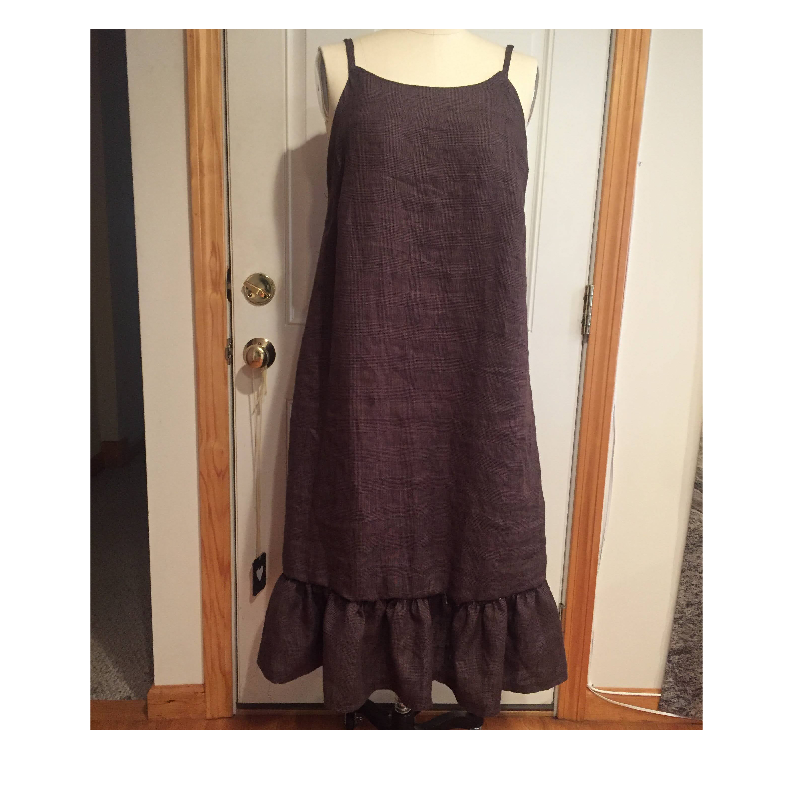

img = imread("../data/dressexample.JPG");
imshow(img)

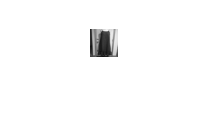

imtiny = imresize(img, [28 28]);
imtiny = rgb2gray(imtiny);
imshow(imtiny)

classify(bestTrainedFromScratch, imtiny)

ans = categorical
     Shirt 


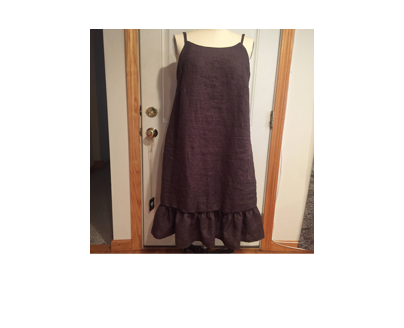

imggoogle = imresize(img, [224 224]);
imshow(imggoogle)

classify(bestTransferLearning, imggoogle)

ans = categorical
     Dress 
